## V2-Pipeline vs Ground Truth LBM Datasets

clc; clear;
plane = 1;

v2 = sprintf('C:/Users/RBO/Documents/data/high_res/extracted_gt/extracted_plane_1.h5');

raw_fpath = 'C:/Users/RBO/Documents/data/ground_truth/high_res/imagedata.mat';
ground_truth = squeeze(matfile(raw_fpath).imageData);
image_series = h5read(v2, '/Y_gt');

## load

figure; subplot(1,2,1); imagesc(image_series(:,:,2)); axis image; axis off; colormap gray;
subplot(1,2,2); imagesc(ground_truth(:,:,2)); axis image; axis off; colormap gray;

isequal(ground_truth, image_series)

ans = logical
   1


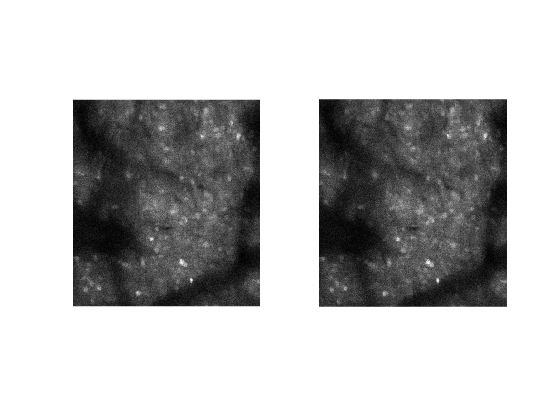

figure; subplot(1,2,1);imagesc(ground_truth(:, :, 2)); axis image; axis tight; axis off;colormap gray;
subplot(1,2,2);
imagesc(image_series(:,:, 2)); axis image; axis tight; axis off;colormap gray

## Extract metrics from Ground Truth data

ground_truth_data = openfig('C:\Users\RBO\Documents\data\ground_truth\high_res\_motion_correction_metrics_plane_30.fig', 'invisible');

% Find all axes objects in the figure
gt_axesObjs = findobj(ground_truth_data, 'Type', 'axes');

% Initialize arrays to store X and Y data
gt_xData = [];
gt_yData = [];

% Loop through each axes object to find line objects and extract data
for i = 1:length(gt_axesObjs)
    % Find all line objects in the current axes
    gt_lineObjs = findobj(gt_axesObjs(i), 'Type', 'line');
    
    % Extract X and Y data from each line object
    for j = 1:length(gt_lineObjs)
        gt_xData = [gt_xData; get(gt_lineObjs(j), 'XData')];
        gt_yData = [gt_yData; get(gt_lineObjs(j), 'YData')];
    end
end

% Close the figure
close(ground_truth_data);

Y_diff = image_shifts(1, :) - transpose(gt_yData(2,:));
Y_diff = abs(Y_diff);
    
% Plot the difference for the current axis
f = figure;
plot(Y_diff(:));
title('Difference in pixel shifts: ground truth vs V2');
xlabel('timestep');
ylabel = ('Number of Pixels in Y');
grid on;

## Comparison

Y_gt = gt_yData(2,:);
shifts_p = transpose(image_shifts(:, 1));
abs_diff1 = abs(shifts_p - Y_gt);
plot(abs_diff1);

## Plot

savep = fullfile(parent_path, 'motion_corrected_gt_plane1.mp4');
img_frame = image_series(:,:,2);
[r, c] = find(img_frame == max(img_frame(:)));
[yind, xind] = get_central_indices(img_frame, r, c, 30);
planeToMovie(e_s, savep, metadata.frame_rate, xind,yind);